# Chapter 3 Implicit Runge-Kutta Methods Examples

#### Example 13

Derive a fourth-order Gauss-Legendre method.

syms a11 a12 a21 a22 b1 b2

% Calculate c coefficients
c = solve(P(2))

$$c = \left(\begin{array}{c} \frac{1}{2}-\frac{\sqrt{3}}{6}\\ \frac{\sqrt{3}}{6}+\frac{1}{2} \end{array}\right)$$

c1 = c(1);
c2 = c(2);

% Define order conditions
eq1 = b1 + b2 == 1;
eq2 = b1 * c1 + b2 * c2 == 1/2;
eq3 = a11 + a12 == c1;
eq4 = a21 + a22 == c2;
eq5 = a11 * c1 + a12 * c2 == 1/2 * c1^2;
eq6 = a21 * c1 + a22 * c2 == 1/2 * c2^2;

% Solve order conditions
solve(eq1, eq2, eq3, eq4, eq5, eq6)

ans = struct with fields:
    a11: 1/4
    a12: -(3^(1/2)*(3^(1/2) - 3)^2)/72
    a21: 3^(1/2)/6 + 1/4
    a22: 1/4
     b1: 1/2
     b2: 1/2


#### Example 14

Derive a third-order Radau IA method.

syms a11 a12 a21 a22 b1 b2 c1 c2

% Calculate c coefficients
c = solve(P(2) + P(1))

$$c = \left(\begin{array}{c} 0\\ \frac{2}{3} \end{array}\right)$$

c1 = c(1);
c2 = c(2);

% Define order conditions
eq1 = b1 + b2 == 1;
eq2 = b2 * c2 == 1/2;
eq3 = b2 * c2 ^ 2 == 1/3;
eq4 = b1 * a11 + b2 * a21 == b1 * (1 - c1);
eq5 = b1 * a12 + b2 * a22 == b2 * (1 - c2);
eq6 = b1 * c1 * a11 + b2 * c2 * a21 == 1/2 * b1 * (1 - c1^2);
eq7 = b1 * c1 * a12 + b2 * c2 * a22 == 1/2 * b2 * (1 - c2^2);

% Solve order conditions
solve(eq1, eq2, eq3, eq4, eq5, eq6)

ans = struct with fields:
    a11: 1/4
    a12: 1
    a21: 1/4
    a22: 0
     b1: 1/4
     b2: 3/4


#### Example 16

The third-order Radau IA implicit Runge-Kutta method is defined by the following Butcher tableau


$$\begin{array}{c|cc}
      0 & \frac{1}{4} & -\frac{1}{4} \\
      \frac{2}{3} & \frac{1}{4} & \frac{5}{12} \\ \hline
      & \frac{1}{4} & \frac{3}{4}
    \end{array}
\end{align*}$$


Use this method to calculate the solution of the following initial value problem using a step length of $h=0.2$ and a convergence tolerance of $tol=10^{-4}$.


$$y' = ty, \qquad t\in [0,1], \qquad y(0)=1.$$


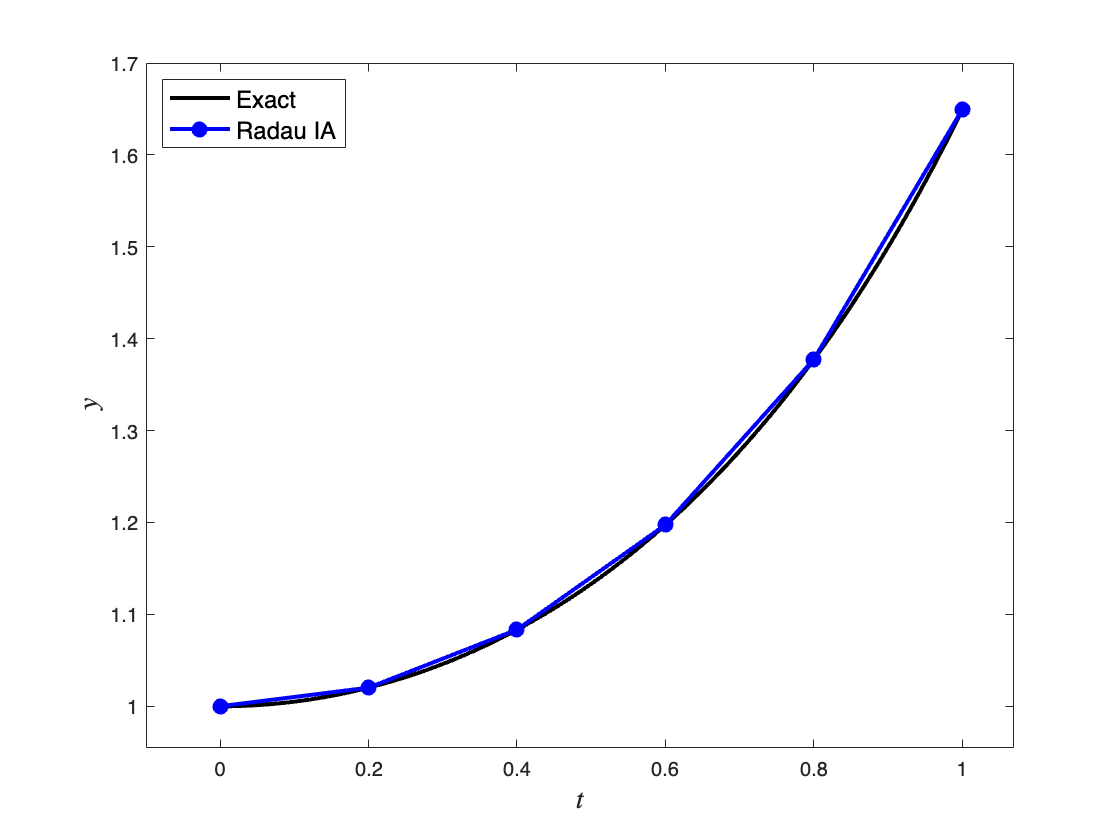

% Define ODE function and exact solution
f = @(t, y) t * y;
exact = @(t) exp(t .^ 2 / 2);

% Define IVP parameters
tspan = [0, 1];     % boundaries of the t domain
y0 = 1;             % initial value of the solution
h = 0.2;            % step length
tol = 1e-4;         % accuracy tolerance

% Calculate the solution to the IVP
[t, y] = solveIVP(f, tspan, y0, h, @radauIA);

% Calculate exact solution for plotting
texact = linspace(tspan(1), tspan(2), 200);
yexact = exact(texact);

% Plot solution
plot(texact, yexact, 'k-', LineWidth=2)
hold on
plot(t, y, 'b-o', LineWidth=2, MarkerFaceColor='b')
hold off
axis padded
xlabel('$t$', FontSize=14, Interpreter='latex')
ylabel('$y$', FontSize=14, Interpreter='latex')
legend('Exact', 'Radau IA', Location='northwest', FontSize=12)

## Functions

#### Single step solver

function [t, y] = solveIVP(f, tspan, y0, h, solver)

% Define t and y arrays
t = (tspan(1) : h : tspan(2));
y = zeros(length(t), length(y0));
y(1,:) = y0;

% Loop through the steps and calculate single step solver solution
for n = 1 : length(t) - 1
    y(n+1,:) = solver(f, t(n), y(n,:), h);
end

end

#### Legendre polynomial

function Pn = P(n)

syms x
Pn = 0;
for k = 0 : n
    Pn = Pn + nchoosek(n, k) * nchoosek(n + k, k) * (x - 1) ^ k;
end

end

#### RadauIA method

function ynew = radauIA(f, t, y, h, tol)

neq = length(y);
Y1 = ones(neq);
Y2 = ones(neq);
Y1old = ones(neq);
Y2old = ones(neq);
for k = 1 : 10
    Y1 = y + h * (1/4 * f(t, Y1) - 1/4 * f(t + 2/3 * h, Y2));
    Y2 = y + h * (1/4 * f(t, Y1) + 5/12 * f(t + 2/3 * h, Y2));
    if max(max(abs(Y1 - Y1old)), max(abs(Y2 - Y2old))) < 1e-4
        break
    end
    Y1old = Y1;
    Y2old = Y2;
end
ynew = y + h / 4 * (f(t, Y1) + 3 * f(t + 2/3 * h, Y2));

end